# Improving Predictive Models

Methods for improving predictive model.

#### Import and Prepare Data

Load the heart disease data and extract numerical predictors.

heartData = readtable("heartDiseaseData.csv");
heartData = convertvars(heartData,12:22,"categorical");
heartDataNum = heartData(:,[1:11 22]);

Partition into training and test sets.

rng(1234)
pt = cvpartition(heartData.HeartDisease,"Holdout",0.2);
hdTrainNum = heartDataNum(training(pt),:);
hdTestNum = heartDataNum(~training(pt),:);
hdTrain = heartData(training(pt),:);
hdTest = heartData(~training(pt),:);

Load the multiclass heart disease data, extract numerical predictors, and partition into training/test sets.

heartDataMulti = readtable("heartDiseaseDataMulticlass.csv");
heartDataMulti = convertvars(heartDataMulti,12:22,"categorical");
hdMTrain = heartDataMulti(training(pt),:);
hdMTest = heartDataMulti(~training(pt),:);
hdMTrainNum = heartDataMulti(training(pt),[1:11 22]);
hdMTestNum = heartDataMulti(~training(pt),[1:11 22]);

## Cross Validation

Create 7-fold cross-validation partition.

part = cvpartition(heartDataNum.HeartDisease,"KFold",7);

Train kNN and DA models.

% kNN
mdlKnn = fitcknn(heartDataNum,"HeartDisease","NumNeighbors",5,"CVPartition",part);
lossKnn = kfoldLoss(mdlKnn);

% Discriminant analysis
mdlDa = fitcdiscr(heartDataNum,"HeartDisease","CVPartition",part);
lossDa = kfoldLoss(mdlDa);

Display the results.

KFoldLoss = [lossKnn;lossDa];
results = table(KFoldLoss);
results.Properties.RowNames = ["kNN" "Discriminant Analysis"];
disp("Seven-fold cross-validated results")

Seven-fold cross-validated results


disp(results)

                             KFoldLoss
                             _________

    kNN                        0.2904 
    Discriminant Analysis     0.26932 



## Hyperparameter Optimization

Optimize all hyperparameters kNN classifier for multiclass numeric heart disease data.

Set optimization options.

cvpt = cvpartition(hdMTrainNum.HeartDisease,"KFold",10);
opt = struct("CVPartition",cvpt,"MaxObjectiveEvaluations",20);

Optimize hyperparameters.

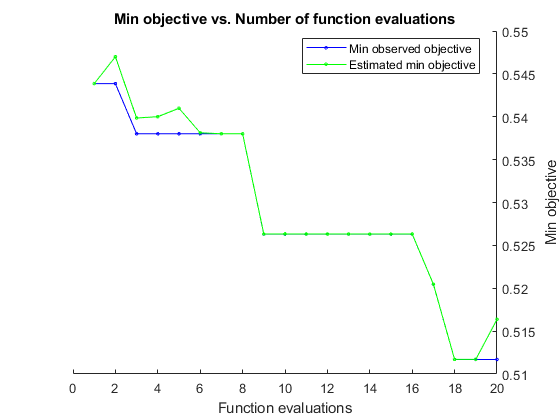

|==================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance | DistanceWeig-|     Exponent |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | ht           |              |              |
|==================================================================================================================================================|
|    1 | Best   |     0.54386 |     0.24472 |     0.54386 |     0.54386 |           29 |      hamming | squaredinver |            - |        false |
|    2 | Accept |     0.62281 |     0.31742 |     0.54386 |       0.547 |            3 |       cosine |        equal |            - |         true |
|    3 | Best   |     0.53801 |     0.30845 |     0.53801 |     0.53985 |          119 |    euclidean | sq

mdl = fitcknn(hdMTrainNum,"HeartDisease",...
    "OptimizeHyperparameters","all","HyperparameterOptimizationOptions",opt);

Calculate loss.

trainLossOpt = resubLoss(mdl)

trainLossOpt = 0

testLossOpt = loss(mdl,hdMTestNum)

testLossOpt = 0.5436

## PCA

Extract response and numerical data.

HD = heartDataNum.HeartDisease;
numData = heartDataNum{:,1:end-1};

Perform PCA.

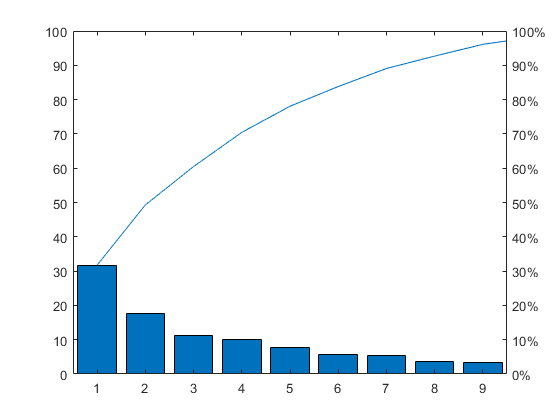

[pcs,scrs,~,~,pexp] = pca(numData);
pareto(pexp)

Visualize principal components.

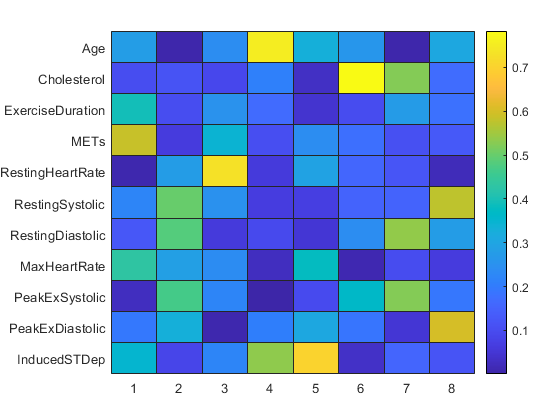

varNames = heartDataNum.Properties.VariableNames(1:end-1);
heatmap(abs(pcs(:,1:8)),"YDisplayLabels",varNames,"Colormap",parula);

Fit Naive Bayes model to original data.

mdlOrig = fitcnb(numData,HD,"DistributionNames","kernel","KFold",10);
lossOrig = kfoldLoss(mdlOrig)

lossOrig = 0.2927

Fit Naive Bayes model to reduced data.

numDataPart = scrs(:,1:8);

numDataPart =     0.1105    0.1089   -0.4042    0.0212    0.2028   -0.0537   -0.0350    0.0884
   -0.0809    0.0750   -0.4009    0.1968    0.0474    0.1480    0.0543    0.0716
   -0.0765   -0.2391   -0.0837    0.0736    0.2836   -0.0581    0.0226    0.1745
    0.5920    0.1121   -0.1163   -0.4166    0.4789    0.0913   -0.2056   -0.0622
    0.2090   -0.0348    0.0836   -0.2165    0.0487    0.0313    0.1505   -0.1157
    0.5692   -0.0778   -0.1129    0.1249    0.2041    0.0019   -0.0195    0.0574
   -0.2675    0.2025   -0.0107   -0.0920    0.3983    0.0359    0.0390    0.1059
    0.1965    0.0043    0.1503    0.1882    0.0553    0.1812   -0.1817    0.1150
   -0.0323   -0.0352    0.0026    0.1261    0.1574    0.1868    0.3468    0.1598
   -0.2570    0.3158    0.0590   -0.2898    0.1685   -0.1400    0.1123    0.2013


mdlPart = fitcnb(numDataPart,HD,"DistributionNames","kernel","KFold",10);
lossPart = kfoldLoss(mdlPart)

lossPart = 0.2740

## Sequential Feature Selection

Create 10-fold partition of mixed heart disease data set.

HD = heartData.HeartDisease;
rng(1234)
cvpt = cvpartition(HD,"KFold",10);

Make dummy variables for categorical predictors.

T = splitvars(convertvars(heartData(:,1:end-1),vartype("categorical"),@dummyvar));
X = T{:,:};
Xnames = T.Properties.VariableNames;

Fit Naive Bayes model to the full data.

dists = [repmat("kernel",1,11),repmat("mvmn",1,10)];
mdlFull = fitcnb(heartData,"HeartDisease","DistributionNames",dists,"CVPartition",cvpt);

Perform sequential feature selection.

rng(1234)
fmodel = @(X,y) fitcnb(X,y,"DistributionNames","kernel");
ferror = @(Xtrain,ytrain,Xtest,ytest) nnz(predict(fmodel(Xtrain,ytrain),Xtest) ~= ytest);
toKeep = sequentialfs(ferror,X,HD,"cv",cvpt,"options",statset("Display","iter"));

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 14, criterion value 0.234192
Step 2, added column 8, criterion value 0.222482
Step 3, added column 11, criterion value 0.213115
Step 4, added column 17, criterion value 0.208431
Step 5, added column 25, criterion value 0.203747
Step 6, added column 2, criterion value 0.199063
Step 7, added column 12, criterion value 0.194379
Step 8, added column 31, criterion value 0.185012
Step 9, added column 1, criterion value 0.18267
Final columns included:  1 2 8 11 12 14 17 25 31 


Which variables are in the final model?

Xnames(toKeep)

ans = 1×9 cell array
    {'Age'}    {'Cholesterol'}    {'MaxHeartRate'}    {'InducedSTDep'}    {'Sex_1'}    {'ChestPainType_1'}    {'ChestPainType_4'}    {'NitratesUsed_1'}    {'ExInducedAngina_1'}


Fit NB model to the selected variables.

mdlPart = fitcnb(X(:,toKeep),HD,"DistributionNames","kernel","CVPartition",cvpt);

Display loss values.

lossFull = kfoldLoss(mdlFull)

lossFull = 0.2131

lossPart = kfoldLoss(mdlPart)

lossPart = 0.1827

## Ensemble Learning

rng(1234)
cvpt = cvpartition(heartData.HeartDisease,"KFold",10);

Train a single decision tree.

mdl = fitctree(heartData,"HeartDisease","CVPartition",cvpt);
singleTLoss = kfoldLoss(mdl)

singleTLoss = 0.2787

Build an ensemble of bagged trees.

rng(1234)
mdl = fitcensemble(heartData,"HeartDisease","Method","Bag",...
    "NumLearningCycles",50,"CVPartition",cvpt);
bagTLoss = kfoldLoss(mdl)

bagTLoss = 0.2319

Try a different ensemble method.

rng(1234)
mdl = fitcensemble(heartData,"HeartDisease","Method","RUSBoost",...
    "Learners","tree","NumLearningCycles",50,"CVPartition",cvpt);
RUSBoostTLoss = kfoldLoss(mdl)

RUSBoostTLoss = 0.2225

Compare a single kNN model to an ensemble of kNN learners.

mdl = fitcknn(heartDataNum,"HeartDisease",...
    "NumNeighbors",5,"DistanceWeight","squaredinverse","CVPartition",cvpt);
singleKLoss = kfoldLoss(mdl)

singleKLoss = 0.2974


knntemp = templateKNN("NumNeighbors",5,"DistanceWeight","squaredinverse");
mdl = fitcensemble(heartDataNum,"HeartDisease","Method","Subspace",...
    "Learners",knntemp,"NumLearningCycles",50,"CVPartition",cvpt);
subspaceKLoss = kfoldLoss(mdl)

subspaceKLoss = 0.3724